# Sistemi LTI: misura di risposta a sinusoide "single tone"

## Simulazione di risposta a sinusoide "single tone"

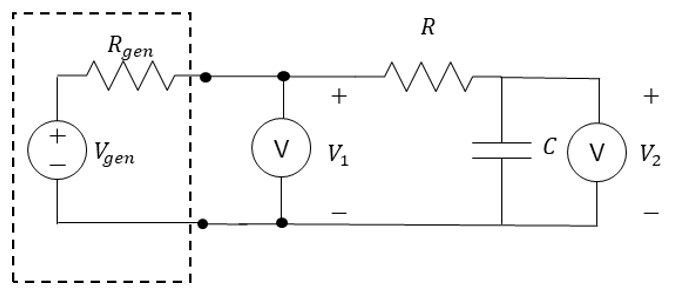

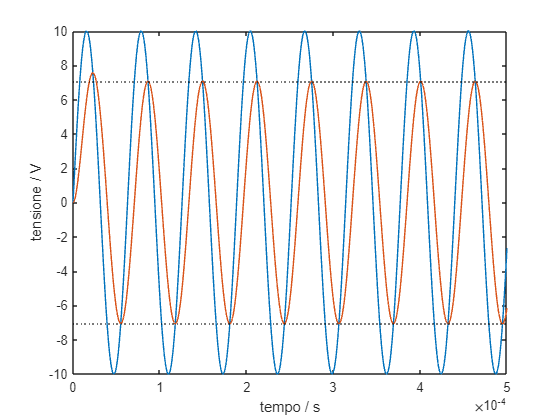

Risposta transitoria con ingresso sinusoidale (sinusoide "single-tone")

% Si simuli la risposta in transitorio al segnale sinusoidale per il circuito in figura.
% Produrre anche un grafico come quello in figura, con evidenziata l'ampiezza della risposta.
%
% Nota: come segnale di ingresso si consideri una sinusoide con valore iniziale = 0 e pendenza
% iniziale positiva.


% Dati
% R = 1e2; % resistenza
% C = 100e-9; % capacità
% s = tf('s') % variabile della trasformata di Laplace
% Td = 50e-5 % durata della simulazione
% N = 1e4; % numero di campioni
% V0 = 10; % ampiezza della sinusoide in ingresso

% Domande
% Rgen = resistenza del generatore
% tau = costante di tempo del sistema, dalla risposta sinusoidale misurata
% fc = frequenza di taglio del sistema, dalla risposta sinusoidale misurata
% H_tf = funzione di trasferimento
% t = vettore colonna di N istanti di tempo equispaziati in [0; Td[
% x = segnale sinusoidale in ingresso, a frequenza fc
% y = risposta al segnale x

% Codice iniziale
clear
format short g

R = 1e2; % resistenza
C = 100e-9; % capacità
s = tf('s'); % variabile della trasformata di Laplace
Td = 50e-5;
N = 1e5;
V0 = 10;

### Soluzione

tau = R*C

tau =         1e-05


H_tf = 1/(1+s*tau)

H_tf =
 
       1
  -----------
  1e-05 s + 1
 
Continuous-time transfer function.



fc = 1/(2*pi*tau)

fc =         15915


Ts = Td/N;
n = (0:N-1)';
t = n*Ts;
f = fc %tensione della sinusoide in ingresso

f =         15915


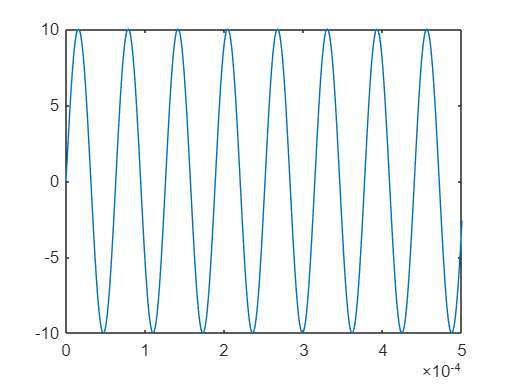

x = V0*sin(2*pi*f*t);
plot(t,x)

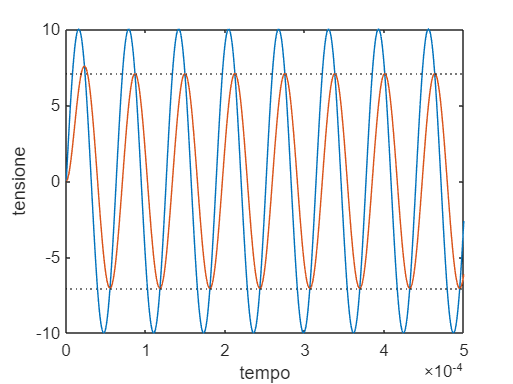

y = lsim(H_tf,x,t); %risposta in transitorio
plot(t,x,t,y)
xlabel('tempo')
ylabel('tensione')
yline([V0/sqrt(2),-V0/sqrt(2)],':k')

## Misura di risposta di ampiezza da sinusoidi single-tone misurate senza errori

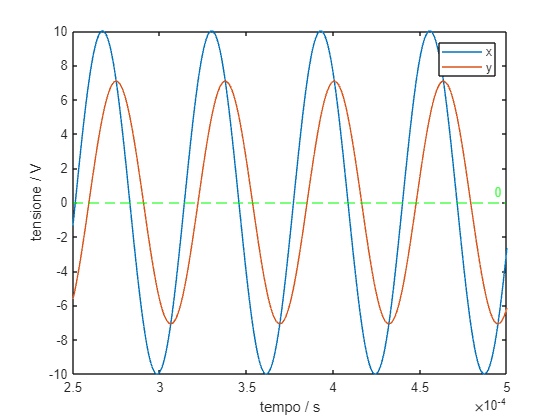

Risposta a regime con ingresso sinusoidale (sinusoide "single tone") - segnali veri

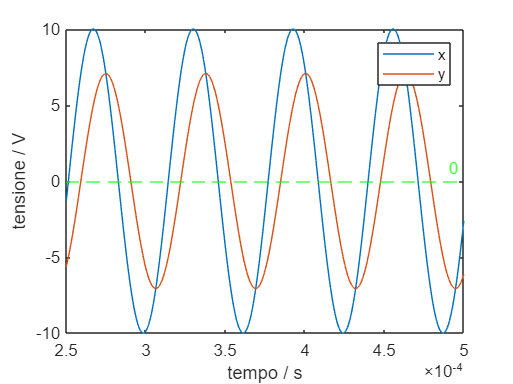

% Per il circuito del quesito precedente, è misurata la risposta single-tone in figura 
% (segnale di ingresso x e segnale di uscita y), alla frequenza f.
% Misurare la risposta di ampiezza del sistema che ha x come ingresso e y come uscita, alla frequenza f. 
% I segnali x e y sono campionati senza errori (segnali veri).

% Dati
% x = segnale in ingresso (vero)
% y = segnale in uscita (vero)

% Domande
% H = risposta di ampiezza alla frequenza f

% Codice iniziale
x1 = x;
x = x1(N/2+1:end); % risposta a regime
y1 = y;
y = y1(N/2+1:end); % risposta a regime
t1 = t;
t = t1(N/2+1:end); % istanti di campionamento
plot(t,x,t,y)
xlabel('tempo / s')
ylabel('tensione / V')
yline(0,'--g',{'0'})
legend('x','y')

### Soluzione

% Soluzione "teorica" affetta dall'errore di offset
Vmaxx = max(x)

Vmaxx =            10


Vmaxy = max(y)

Vmaxy =        7.0711


H = Vmaxy/Vmaxx

H =       0.70711


% Soluzione alternativa, non affetta dall'errore di offset
Vppx = range(x)

Vppx =            20


Vppy = range(y)

Vppy =        14.142


H = Vppy/Vppx

H =       0.70711


## Misura di risposta di ampiezza da sinusoidi single-tone misurate con *uguali* errori di guadagno e offset

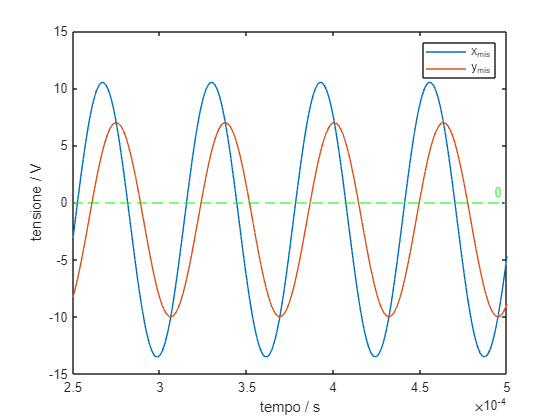

Risposta a regime con ingresso sinusoidale (sinusoide "single tone") - segnali misurati con errori di guadagno e offset

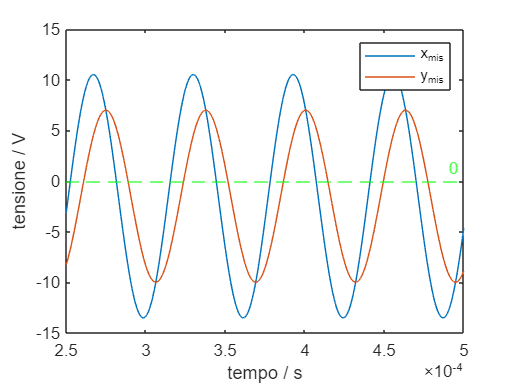

% Per il circuito del quesito precedente, è misurata la risposta single-tone in figura 
% (segnale di ingresso x e segnale di uscita y), alla frequenza f.

% Misurare la risposta di ampiezza del sistema che ha x come ingresso e y come uscita, alla frequenza f. 

% Si tenga conto che i segnali sono misurati con uguali errori di guadagno e di offset, cioè, detti x e y i segnali veri:
% xmis = (1+erG)*x + eO
% ymis = (1+erG)*y + eO
% dove erG (adimensionale) è l'errore relativo di guadagno, mentre eO (volt) è l'errore dSi offset.

% Dati
% xmis = segnale in ingresso (misurato con errori di guadagno e offset) 
% ymis = segnale in uscita (misurato con errori di guadagno e offset) 

% Domande
% Hmis = risposta di ampiezza alla frequenza f (misurata da xmis, ymis)

% Codice iniziale
erG = 0.2; % errore (relativo) di guadagno dello strumento di misura, pari al 20%
eO = -15/100*V0; % errore di offset dello strumento di misura, pari a -15% di V0

xmis = x*(1+erG) + eO; % segnale di ingresso misurato con errori di offset e di guadagno
ymis = y*(1+erG) + eO; % segnale di uscita misurato con errori di offset e di guadagno
plot(t,xmis,t,ymis)
xlabel('tempo / s')
ylabel('tensione / V')
yline(0,'--g',{'0'})
legend('x_{mis}','y_{mis}')

### Soluzione

% Soluzione affetta dall'errore di offset
Vmaxx = max(xmis)

Vmaxx =          10.5


Vmaxy = max(ymis)

Vmaxy =        6.9853


Hmis = Vmaxy/Vmaxx

Hmis =       0.66526


% Soluzione non affetta dall'errore di offset
Vppx = range(xmis)

Vppx =            24


Vppy = range(ymis)

Vppy =        16.971


Hmis = Vppy/Vppx

Hmis =       0.70711


## Misura di frequenza di taglio e di capacità dalla risposta di ampiezza

% Per il circuito del quesito precedente, è misurata la risposta di ampiezza H alla frequenza f.
% Misurare la frequenza di taglio fc del sistema che ha H come risposta di ampiezza.
% Misurare la capacità C del circuito.

% Dati
% H = risposta di ampiezza
% f = frequenza del segnale sinusoidale
% R = resistenza nel circuito RC

% Domande
% fc = frequenza di taglio del sistema di cui si è misurata la risposta di ampiezza
% C = capacità del circuito

### Soluzione

E' una conseguenza di $H=\frac{1}{\sqrt{1+{\left(\frac{f}{f_c }\right)}^2 \;}}$, e di $f_c =\frac{1}{2\pi \;\tau \;}$ con $\tau =\textrm{RC}$

fc = f*H/sqrt(1-H^2)

fc =         15915


C = 1/(2*pi*fc*R)

C =         1e-07


## Misura di risposta di fase da sinusoidi single-tone misurate senza errori

% Per il circuito del quesito precedente, è misurata la risposta single-tone in figura 
% (segnale di ingresso x e segnale di uscita y), alla frequenza f.
% Misurare la risposta di fase del sistema che ha x come ingresso e y come uscita, alla frequenza f. 
% I segnali x e y sono campionati senza errori (segnali veri).

% Dati
% x = segnale in ingresso (vero)
% y = segnale in uscita (vero)
% t = istanti di tempo dei campioni x e y

% Domande
% dt = % shift temporale tra x e y in secondi, con lo stesso di phiH
% phiH = risposta di fase in radianti alla frequenza f
% phiH_deg = risposta di fase in gradi alla frequenza f

### Soluzione

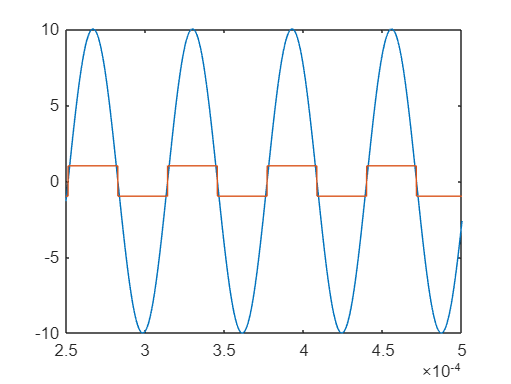

plot(t,x,t,sign(x))

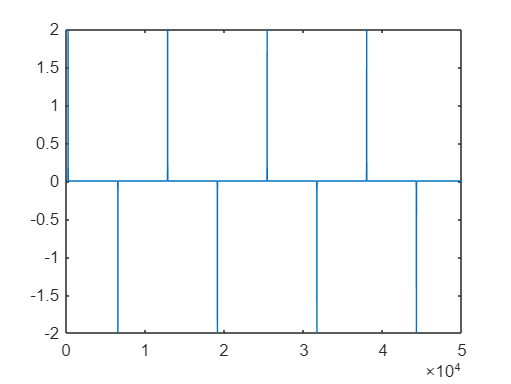

plot(diff(sign(x))) %individua i campioni in cui si passa dallo zero con pendenza positiva o negativa

ix = find(diff(sign(x))<0, 1)

ix =         6549


tx = t(ix)

tx =    0.00028274


iy = find(diff(sign(y))<0, 1)

iy =         8120


ty = t(iy)

ty =    0.00029059


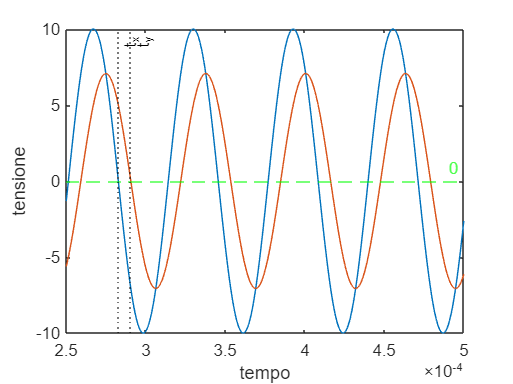

plot(t,x,t,y)
xlabel('tempo')
ylabel('tensione')
yline(0,'--g',{0})
xline([tx,ty],':k',{'t_x','t_y'})

dt = tx-ty

dt =    -7.855e-06


phiH = 2*pi*f*dt

phiH =       -0.7855


phiH_deg = phiH*180/pi

phiH_deg =       -45.006


## Misura di risposta di fase da sinusoidi single-tone misurate con *uguali* errori di guadagno e offset, con campioni equispaziati in un numero intero di periodi

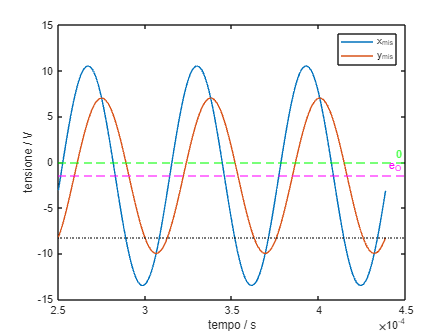

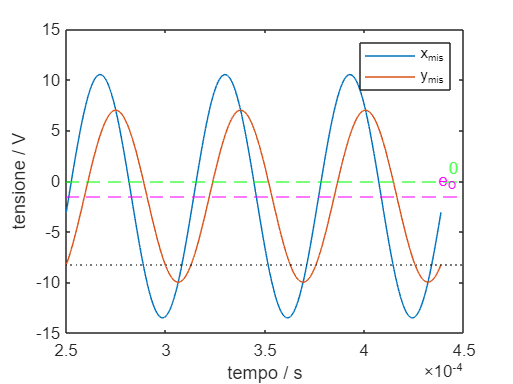

% Per il circuito del quesito precedente, è misurata la risposta single-tone in figura 
% (segnale di ingresso x e segnale di uscita y), alla frequenza f.
% Misurare la risposta di fase del sistema che ha x come ingresso e y come uscita, alla frequenza f. 
% Si tenga conto che i segnali sono misurati con uguali errori di guadagno e di offset, cioè, detti x e y i segnali veri:
% xmis = (1+erG)*x + eO
% ymis = (1+erG)*y + eO
% dove erG (adimensionale) è l'errore relativo di guadagno, mentre eO (volt) è l'errore di offset.

% Dati
% xmis = segnale in ingresso (misurato con errori di guadagno e offset) 
% ymis = segnale in uscita (misurato con errori di guadagno e offset)
% tmis = istanti di tempo dei campioni x e y

% Domande
% dt = % shift temporale tra x e y in secondi, con lo stesso di phiH
% phiHmis = risposta di fase in radianti alla frequenza f
% phiHmis_deg = risposta di fase in gradi alla frequenza f

% Codice iniziale
tmis = t((1:end-12300)); % questo "taglio" fa sì che i campioni siano equispaziati in un numero approx intero di periodi
xmis = x(1:end-12300)*(1+erG) + eO; % segnale di ingresso misurato con errori di offset e di guadagno
ymis = y(1:end-12300)*(1+erG) + eO; % segnale di uscita misurato con errori di offset e di guadagno

plot(tmis,xmis,tmis,ymis)
xlabel('tempo / s')
ylabel('tensione / V')
yline(0,'--g',{'0'})
yline(eO,'--m',{'e_O'})
yline(ymis(1),':k')
legend('x_{mis}','y_{mis}')

### Soluzione

In linea di principio potremmo individuare i primi massimi (o minimi) dei segnali. Tuttavia, questo metodo è affetto da incertezza piuttosto grande anche in presenza di errori di misura molto piccoli.

In presenza di errori p. es. dovuti al rumore:

1) I "massimi" sono in realtà tutti massimi locali, quindi bisogna cercare il primo massimo locale;

2) Il massimo locale in presenza di rumore è comunque molto incerto.

Bisogna individuare i passaggi dallo zero, ma per fare questo occorre considerare l'errore di offset, che fa sì che i segnali non siano a media nulla.

% Calcolo di componente DC e AC dei segnali
% Questo semplice metodo funziona solo se i campioni equispaziati in un numero intero di
% periodi; altrimenti fornisce risultati errati. Il metodo OLS fornisce invece sempre una
% stima ottima, con grande semplicità; ma necessita del modello del segnale.

% xmis_DC = mean(xmis) % operazione da eseguire: misura della componente continua
% xmis_AC = xmis - xmis_DC; % operazione da eseguire: sottrazione della componente continua

% Verifichiamo il numero intero di periodi
Ts %periodo di campionamento

Ts =         5e-09


Nmis = length(xmis) %numero di campioni

Nmis =        37700


Tdmis = Nmis*Ts %durata

Tdmis =     0.0001885


Npmis = f*Tdmis %numero di periodi

Npmis =        3.0001


% Misuriamo la componente DC, che è uguale all'errore di offset. 
% Questa operazione è eseguita con lo scopo di eliminarla, ottenendo solo la componente AC del segnale.
xmis_DC = mean(xmis)

xmis_DC =          -1.5


ymis_DC = mean(ymis)

ymis_DC =       -1.5002


% eliminiamo la componente DC
xmis_AC = xmis - xmis_DC;
ymis_AC = ymis - ymis_DC;
% Ricerca del primo passaggio per lo zero con pendenza negativa
ix = find(diff(sign(xmis_AC))<0,1)

ix =         6549


tx = tmis(ix)

tx =    0.00028274


iy = find(diff(sign(ymis_AC))<0,1)

iy =         8120


ty = tmis(iy)

ty =    0.00029059


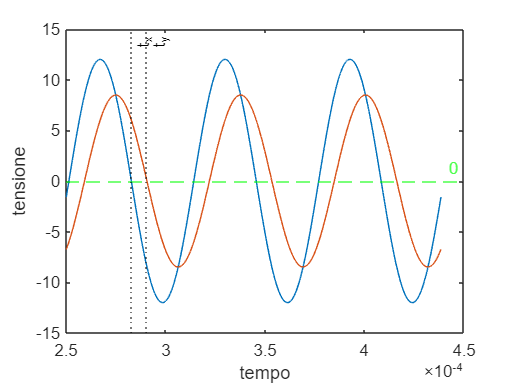


plot(tmis,xmis_AC,tmis,ymis_AC)
xlabel('tempo')
ylabel('tensione')
yline(0,'--g',{'0'})
xline([tx,ty],':k',{'t_x','t_y'})


dt = tx-ty

dt =    -7.855e-06


phiHmis = 2*pi*f*dt

phiHmis =       -0.7855


phiHmis_deg = phiHmis*180/pi

phiHmis_deg =       -45.006


## Misura di frequenza di taglio e di capacità dalla risposta di fase

% Per il circuito del quesito precedente, è misurata la risposta di ampiezza phiH alla frequenza f.
% Misurare la frequenza di taglio fc (del sistema che ha phiH come risposta di fase).
% Misurare la capacità C del circuito.

% Dati
% phiH = risposta di fase
% f = frequenza del segnale sinusoidale
% R = resistenza nel circuito RC

% Domande
% fc = frequenza di taglio del sistema di cui si è misurata la risposta di ampiezza
% C = capacità del circuito

### Soluzione

E' una conseguenza di $\varphi_H =0-\textrm{atan}\left(\frac{f}{f_c }\right)=-\textrm{atan}\left(\frac{f}{f_c }\right)$, ecc.

fc = tan(-phiH)*f

fc =         15919


fc = tan(-phiHmis)*f

fc =         15919


C = 1/(2*pi*R*fc)

C =     9.998e-08
